## 初始化

clc;
clear;

## 参数设置

M = 1.5e3;          %采样点个数
Fs = 15e6;          %采样率

## 文件读取

pathname = 'Single_data.xlsx';
wave_data = readmatrix(pathname);
vout = wave_data(1:M,1);

## 绘制时域波形图

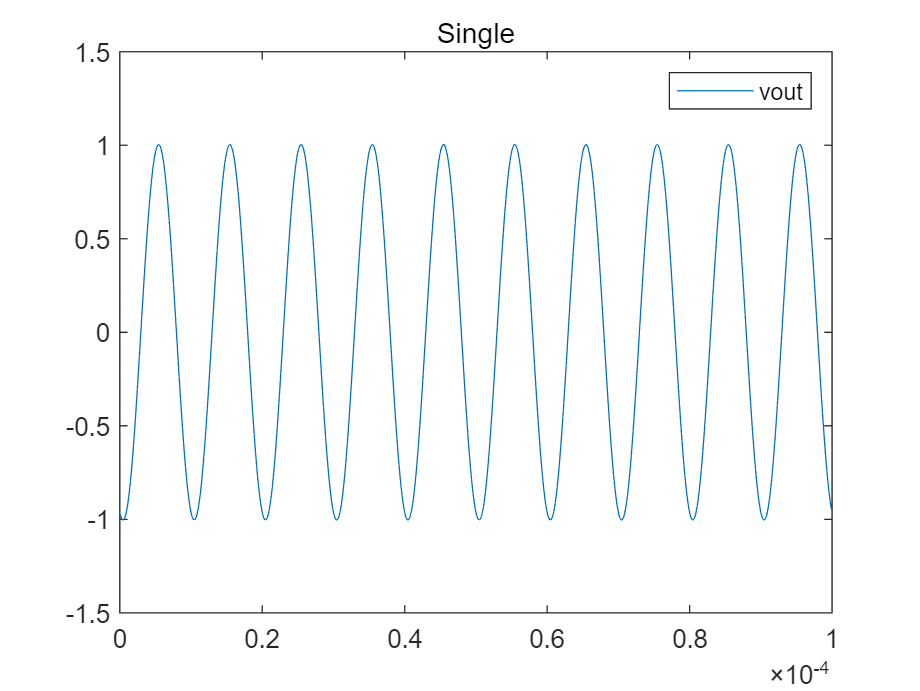

plot(0:1/(15e6):(M - 1)/15e6, vout(1:M,1));
legend("vout");
title("Single");

## 计算vout的THD、SINAD与SNR

NumHarmonics = 5;                                       %保留的谐波个数
[thd_db,harmpow,harmfreq] = thd(vout,Fs,NumHarmonics); %计算thd，单位为dB        
percent_thd = 100*(10^(thd_db/20));                     %转换为百分比
T = table(harmfreq,harmpow,'VariableNames',{'Frequency','Power'});
disp(T);                                                %列举频率与功率值

    Frequency      Power 
    __________    _______

         1e+05    -2.9853
       1.9e+05    -94.382
    3.0941e+05     -98.33
    3.9718e+05    -107.87
       4.9e+05    -105.24



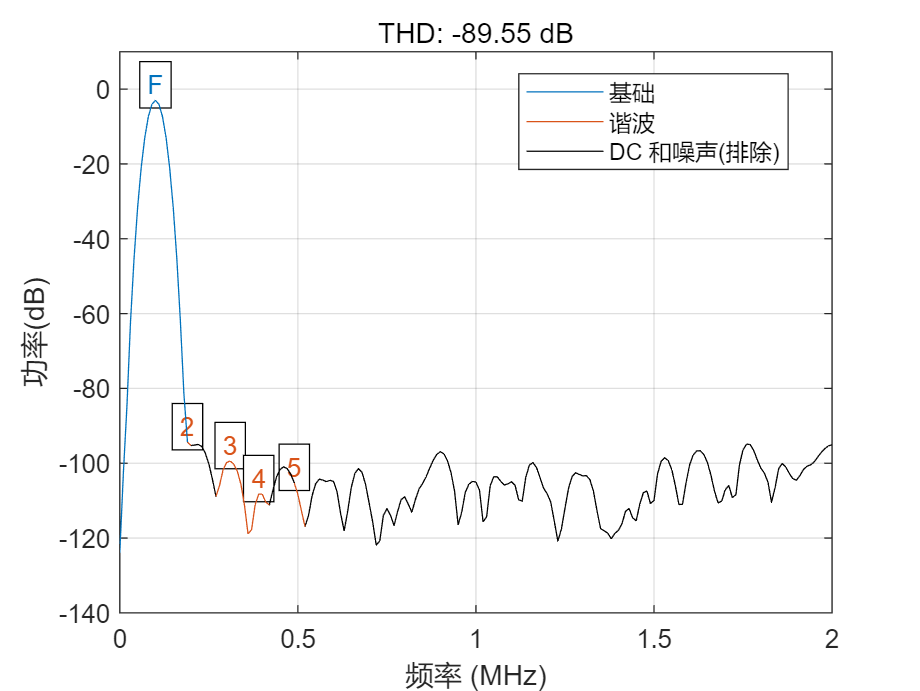

thd(vout, Fs, NumHarmonics);                           %画出谐波图

xlim([0.00 2.00])
ylim([-140 10])

display(percent_thd);                                  %打印最终总谐波失真（百分比）

percent_thd = 0.0033


SNR = snr(vout,Fs);                                        %计算SNR
SINAD = sinad(vout,Fs);                                    %计算SINAD

fprintf('Vout_SNR = %.10gdB\n',SNR); 

Vout_SNR = 65.97180638dB


fprintf('Vout_SINAD = %.10gdB\n',SINAD); 

Vout_SINAD = 65.97543751dB
